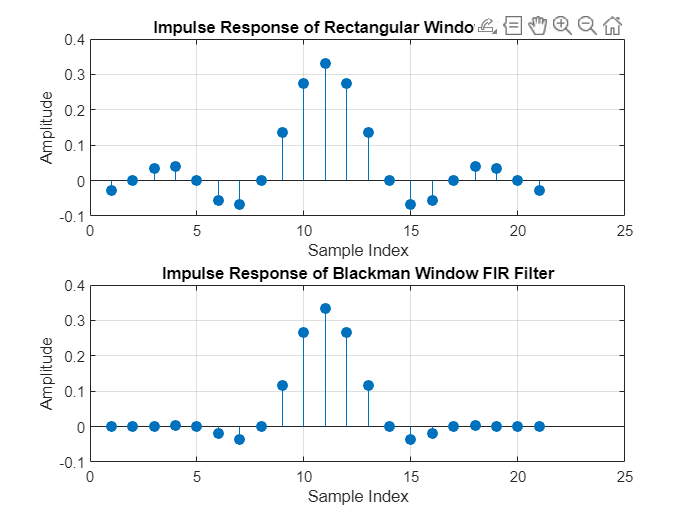

alpha = 2;
wc = pi / (alpha + 1);
N = 21;

h_blackman = fir1(N - 1, wc / pi, 'low', blackman(N));
h_rectangular = fir1(N - 1, wc / pi, 'low', rectwin(N));

figure;
subplot(2, 1, 1);
stem(h_rectangular, 'filled');
title('Impulse Response of Rectangular Window FIR Filter');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
stem(h_blackman, 'filled');
title('Impulse Response of Blackman Window FIR Filter');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

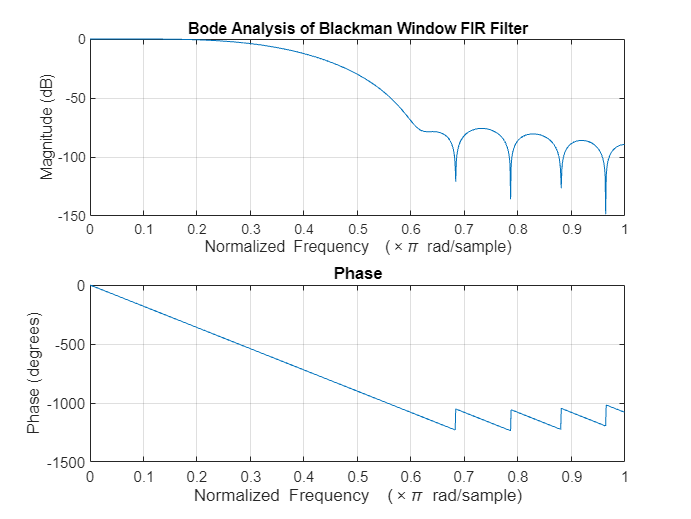


figure;
freqz(h_blackman, 1, 1024);
title('Bode Analysis of Blackman Window FIR Filter');

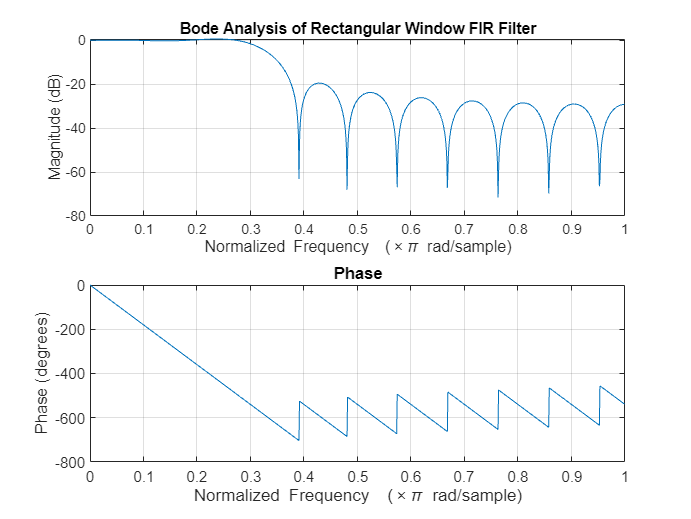


figure;
freqz(h_rectangular, 1, 1024);
title('Bode Analysis of Rectangular Window FIR Filter');alpha = 2;

wc = pi / (alpha + 1);
N = 21;